# MERRA2 Profile Builder

**Authors:** Michael Pupillo and Dr. Chris Heale

**Project:** Convectional Gravity Waves in the Stratosphere [CGWaveS]

**Inputs:** MERRA-2 inst3_3d_asm_Np: 3d, 3-Hourly, Instantaneous, Pressure Level, Assimilation, Assimilated Meteorological Fields V5.12.4 (M213NPASM) files found on gsfc.nasa.gov EarthData GES DISC

**Outputs:** data text file [ background.wind , background_plus_stdev.wind , background_minus_stdev.wind ] for CGCAM

## Define Search Parameters

clear all
clc

% Define time instance measurements 1 through 8 of any given day
timein1 = 1;         % measurement index at a given time (data instantaneous measurement every 3 hours)
timein2 = 2;         % maximum 8 in 24 hr period
day = 1:30 ;          % individual day or range of days

% Define altitude of interest and resolution
alt_step = 0.0625;       % altitude step size in km (resolution)
alt_low = 0;        % lower altitude limit in km
alt_high = 34;      % upper altitude limit in km

% Define area of interest
latlim1 = 36;       % smaller number
latlim2 = 43;         % larger number
lonlim1 = -106;        % smaller number
lonlim2 = -100;      % larger number


## File Information / Raw Data

% % .nc4 file information

% % % % ncinfo('MERRA2_1NOV2022.nc4')
% % % % ncdisp('MERRA2_1NOV2022.nc4')

% % Edge Heights (Altitude) "H" raw data
% H = ncread('MERRA2_1NOV2022.nc4','H');
% size(H);
% % Zonal Wind "U" raw data
% U = ncread('MERRA2_1NOV2022.nc4','U');
% size(U);
% % Meridional Wind "V" raw data
% V = ncread('MERRA2_1NOV2022.nc4','V');
% size(V);
% % Air Temperature "T" [K] raw data
% T = ncread('MERRA2_1NOV2022.nc4','T');
% size(T);
% % Longitude raw data
% lon = ncread('MERRA2_1NOV2022.nc4','lon');
% size(lon);
% % Latitude raw data
% lat = ncread('MERRA2_1NOV2022.nc4','lat');
% size(lat);


## Call file for each day

filename = dir(fullfile('C:','Users','mapup','MATLAB Drive','MERRA2_11May','*.nc4'));

for d = 1:length(day)
    
%     H(:,:,:,:,d) = ncread(filename(day(d)).name,'H');
%     U(:,:,:,:,d) = ncread(filename(day(d)).name,'U');
%     V(:,:,:,:,d) = ncread(filename(day(d)).name,'V');
%     T(:,:,:,:,d) = ncread(filename(day(d)).name,'T');
%     lon(:,:,:,:,d) = ncread(filename(day(d)).name,'lon');
%     lat(:,:,:,:,d) = ncread(filename(day(d)).name,'lat');

%%%Remove the d index, not needed actually! Waste of memory
    H = ncread(filename(day(d)).name,'H');
    U = ncread(filename(day(d)).name,'U');
    V = ncread(filename(day(d)).name,'V');
    T = ncread(filename(day(d)).name,'T');
    lon = ncread(filename(day(d)).name,'lon');
    lat = ncread(filename(day(d)).name,'lat');
 
%index to average over area

%     [A,latI1]=(min(abs(lat(:,:,:,:,d)-latlim1)));
%     [A,latI2]=(min(abs(lat(:,:,:,:,d)-latlim2)));
%     [A,lonI1]=(min(abs(lon(:,:,:,:,d)-lonlim1)));
%     [A,lonI2]=(min(abs(lon(:,:,:,:,d)-lonlim2)));

%%% Remove d index again, not needed
    [A,latI1]=(min(abs(lat-latlim1)));
    [A,latI2]=(min(abs(lat-latlim2)));
    [A,lonI1]=(min(abs(lon-lonlim1)));
    [A,lonI2]=(min(abs(lon-lonlim2)));

    latI1 = squeeze(latI1);
    latI2 = squeeze(latI2);
    lonI1 = squeeze(lonI1);
    lonI2 = squeeze(lonI2);

% Reduce to single array


%     H_sq = squeeze(mean(squeeze(mean(squeeze(mean(H(lonI1:lonI2,latI1:latI2,:,timein1:timein2,d),1,'omitnan')),1,'omitnan')),2,'omitnan'))./1000;  % divide by 1000 to convert to km
%     U_sq = squeeze(mean(squeeze(mean(squeeze(mean(U(lonI1:lonI2,latI1:latI2,:,timein1:timein2,d),1,'omitnan')),1,'omitnan')),2,'omitnan'));
%     V_sq = squeeze(mean(squeeze(mean(squeeze(mean(V(lonI1:lonI2,latI1:latI2,:,timein1:timein2,d),1,'omitnan')),1,'omitnan')),2,'omitnan'));
%     T_sq = squeeze(mean(squeeze(mean(squeeze(mean(T(lonI1:lonI2,latI1:latI2,:,timein1:timein2,d),1,'omitnan')),1,'omitnan')),2,'omitnan'));


%%% remove d index and change nanmean to mean(X,dim,'omitnan'), also
%%% indexing was wrong for lat, lon, check this with Michael
    H_sq = squeeze(mean(squeeze(mean(squeeze(mean(H(lonI1:lonI2,latI1:latI2,:,timein1:timein2),1,'omitnan')),1,'omitnan')),2,'omitnan'))./1000;  % divide by 1000 to convert to km
    U_sq = squeeze(mean(squeeze(mean(squeeze(mean(U(lonI1:lonI2,latI1:latI2,:,timein1:timein2),1,'omitnan')),1,'omitnan')),2,'omitnan'));
    V_sq = squeeze(mean(squeeze(mean(squeeze(mean(V(lonI1:lonI2,latI1:latI2,:,timein1:timein2),1,'omitnan')),1,'omitnan')),2,'omitnan'));
    T_sq = squeeze(mean(squeeze(mean(squeeze(mean(T(lonI1:lonI2,latI1:latI2,:,timein1:timein2),1,'omitnan')),1,'omitnan')),2,'omitnan'));

% Interpolate data sets


%% added (~isnan(H_sq)) to ignore nan points when interpolating, here we do definitely need the d index though.
    H_interp = [ alt_low : alt_step : alt_high ];
    U_interp(d,:) = interp1(H_sq(~isnan(H_sq)),U_sq(~isnan(H_sq)),H_interp,"pchip");
    V_interp(d,:) = interp1(H_sq(~isnan(H_sq)),V_sq(~isnan(H_sq)),H_interp,"pchip");
    T_interp(d,:) = interp1(H_sq(~isnan(H_sq)),T_sq(~isnan(H_sq)),H_interp,"pchip");
    
end
    
% Time average

U_interp_time_avg = squeeze(mean(U_interp,1,'omitnan'));
V_interp_time_avg = squeeze(mean(V_interp,1,'omitnan'));
T_interp_time_avg = squeeze(mean(T_interp,1,'omitnan'));

% Force winds to zero at ground level
    
wind_0 = linspace(0,1,8e3/(alt_step*1000));
U_interp_time_avg(1:2) = 0;
V_interp_time_avg(1:2) = 0;
U_interp_time_avg(3:2+length(wind_0)) = U_interp_time_avg(3:2+length(wind_0)).*wind_0;
V_interp_time_avg(3:2+length(wind_0)) = V_interp_time_avg(3:2+length(wind_0)).*wind_0;
    

% VARIANCE
%% Variance of each selected day(s)
U_var = squeeze(var(U_interp,'omitnan'));

V_var = squeeze(var(V_interp,'omitnan'));

T_var = squeeze(var(T_interp,'omitnan'));


% Find Weak, Medium, Strong and Mean Profiles within Data File
    
    % STRONG
    [U_var_strong, I] = max(squeeze(var(U_interp,0,2,'omitnan')))

U_var_strong = 141.1492

I = 9

    
    [V_var_strong, I] = max(squeeze(var(V_interp,0,2,'omitnan')))

V_var_strong = 96.0900

I = 14

    
    [T_var_strong, I] = max(squeeze(var(T_interp,0,2,'omitnan')))

T_var_strong = 640.5925

I = 17

    
    % MEAN
    U_mean = mean(U_interp(:))

U_mean = 5.1867

    
    V_mean = mean(V_interp(:))

V_mean = 0.8900

    
    T_mean = mean(T_interp(:))

T_mean = 233.4192

    
    % MEDIAN
    U_median = median(U_interp(:))

U_median = 3.9992

    
    V_median = median(V_interp(:))

V_median = -0.2449

    
    T_median = median(T_interp(:))

T_median = 225.0171

    
    % MODE
    U_mode = mode(U_interp(:))

U_mode = -23.5579

    
    V_mode = mode(V_interp(:))

V_mode = -28.2094

    
    T_mode = mode(T_interp(:))

T_mode = 206.2740

    
    % WEAK
    [U_var_weak, I] = min(squeeze(var(U_interp,0,2,'omitnan')))

U_var_weak = 6.8977

I = 12

    
    [V_var_weak, I] = min(squeeze(var(V_interp,0,2,'omitnan')))

V_var_weak = 2.9564

I = 29

    
    [T_var_weak, I] = min(squeeze(var(T_interp,0,2,'omitnan')))

T_var_weak = 517.9384

I = 1

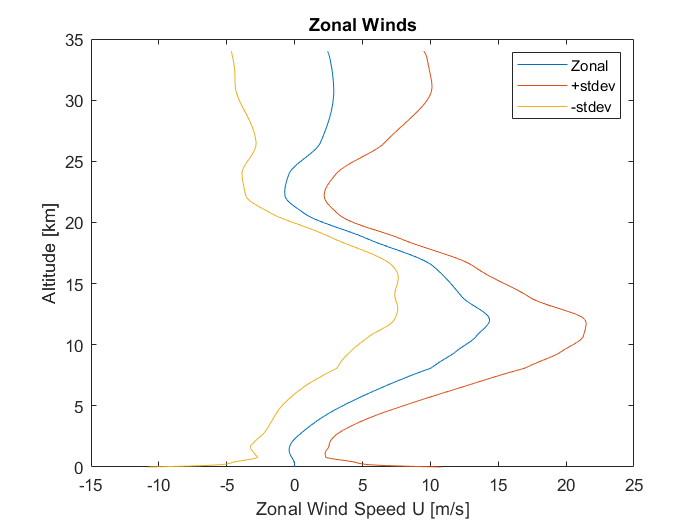



figure(1)
% Zonal Wind
plot(U_interp_time_avg,H_interp,U_interp_time_avg+sqrt(U_var),H_interp,U_interp_time_avg-sqrt(U_var),H_interp)
ylabel("Altitude [km]")
xlabel("Zonal Wind Speed U [m/s]")
legend('Zonal','+stdev','-stdev')
title('Zonal Winds')    % add location area

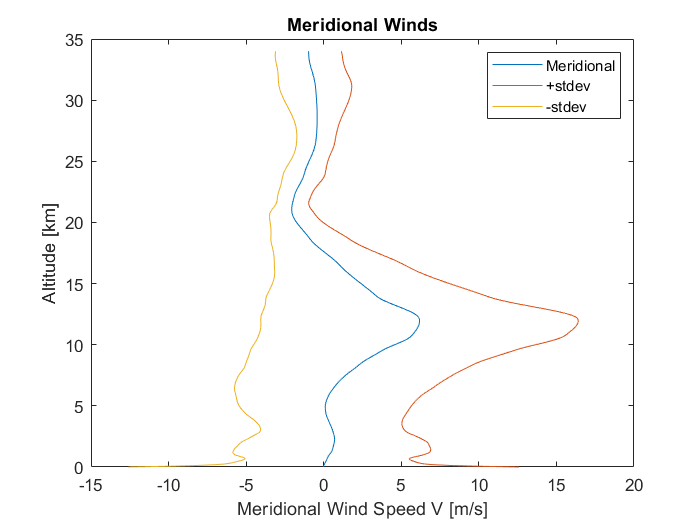


% Meridional Wind
plot(V_interp_time_avg,H_interp,V_interp_time_avg+sqrt(V_var),H_interp,V_interp_time_avg-sqrt(V_var),H_interp)
ylabel("Altitude [km]")
xlabel("Meridional Wind Speed V [m/s]")
legend('Meridional','+stdev','-stdev')
title('Meridional Winds')    % add location area

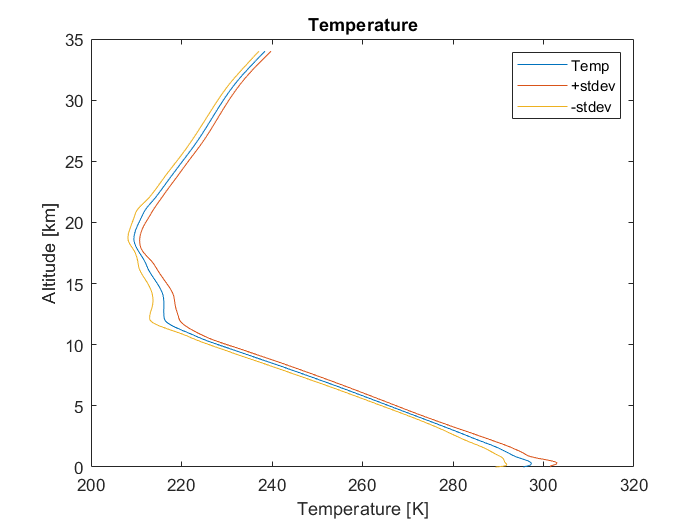


% Temperature vs Altitude
figure(2)
plot(T_interp_time_avg,H_interp,T_interp_time_avg+sqrt(T_var),H_interp,T_interp_time_avg-sqrt(T_var),H_interp)
ylabel("Altitude [km]")
xlabel("Temperature [K]")
legend('Temp','+stdev','-stdev')
title('Temperature')   % add location area

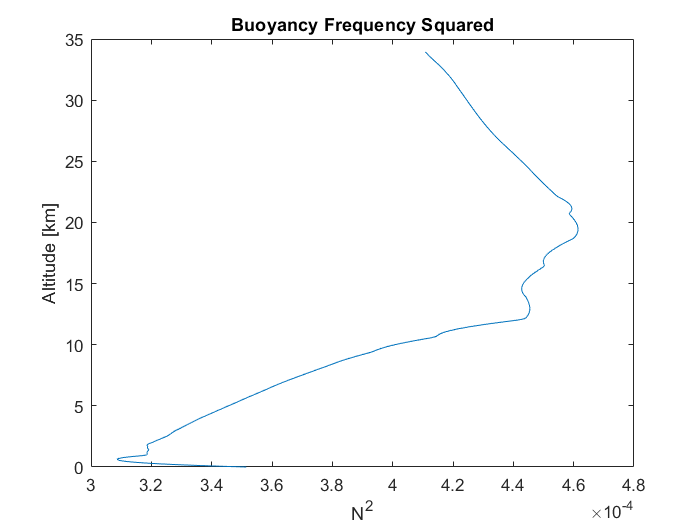


% Buoncy Frequency Squared (Brunt-Vaisala Frequency)
g = 9.81;   % [m/s^2]

dTdz = diff(T_interp_time_avg(:,:))./1000;
N2 = (g./T_interp_time_avg(:,1:end-1).*(dTdz + (g/1000))); 
    
figure(3)
plot(N2,H_interp(1:end-1))
ylabel("Altitude [km]")
xlabel("N^2")
title('Buoyancy Frequency Squared')


% Write output text file for CGCAM
%%% builds a text file with columns of altitude, zonal, meridional wind and
%%% temperature respectively

% Interpolated Time Averaged Data
profile1 = [ H_interp' U_interp_time_avg' V_interp_time_avg' T_interp_time_avg' ]

profile1 =          0         0         0  295.5053
    0.0625         0         0  296.2821
    0.1250         0         0  296.8291
    0.1875   -0.0047    0.0261  297.1688
    0.2500   -0.0098    0.0526  297.3238
    0.3125   -0.0170    0.0790  297.3165
    0.3750   -0.0277    0.1049  297.1695
    0.4375   -0.0428    0.1300  296.9053
    0.5000   -0.0629    0.1542  296.5463
    0.5625   -0.0878    0.1775  296.1152


fid=fopen('background.wind', 'wt');
fprintf(fid, '%s\t%s\t%s\t%s\n', 'z','u','v','T');  % header
fclose(fid);
dlmwrite('background.wind',profile1,'delimiter','\t','precision','%.6E','-append');

% Plus Standard Deviation

profile2 = [ H_interp' (U_interp_time_avg+sqrt(U_var))' (V_interp_time_avg+sqrt(V_var))' (T_interp_time_avg+sqrt(T_var))' ]

profile2 =          0   10.7902   12.5906  301.6108
    0.0625    8.2378    9.9676  301.4805
    0.1250    6.5024    8.1529  301.8786
    0.1875    5.4802    7.0609  302.4337
    0.2500    4.9695    6.4787  302.8519
    0.3125    4.7111    6.1895  303.0006
    0.3750    4.5030    6.0208  302.8513
    0.4375    4.2399    5.8772  302.4280
    0.5000    3.8929    5.7306  301.7802
    0.5625    3.4816    5.5968  300.9712


fid=fopen('background_plus_stdev.wind', 'wt');
fprintf(fid, '%s\t%s\t%s\t%s\n', 'z','u','v','T');  % header
fclose(fid);
dlmwrite('background_plus_stdev.wind',profile2,'delimiter','\t','precision','%.6E','-append');

% Minus Standard Deviation

profile3 = [ H_interp' (U_interp_time_avg-sqrt(U_var))' (V_interp_time_avg-sqrt(V_var))' (T_interp_time_avg-sqrt(T_var))' ]

profile3 =          0  -10.7902  -12.5906  289.3999
    0.0625   -8.2378   -9.9676  291.0837
    0.1250   -6.5024   -8.1529  291.7796
    0.1875   -5.4897   -7.0088  291.9039
    0.2500   -4.9891   -6.3735  291.7957
    0.3125   -4.7451   -6.0315  291.6325
    0.3750   -4.5585   -5.8110  291.4877
    0.4375   -4.3256   -5.6172  291.3826
    0.5000   -4.0187   -5.4223  291.3125
    0.5625   -3.6573   -5.2418  291.2592


fid=fopen('background_minus_stdev.wind', 'wt');
fprintf(fid, '%s\t%s\t%s\t%s\n', 'z','u','v','T');  % header
fclose(fid);
dlmwrite('background_minus_stdev.wind',profile3,'delimiter','\t','precision','%.6E','-append');



